## 题目1

考察以下线性系统


$$\frac{d^3}{dt^3} x(t) + 10 \frac{d^2}{dt^2} x(t) +  32 \frac{d^2}{dt^2} x(t)  +  6\frac{d}{dt} x(t) + 7x(t) = u(t) $$


完成以下内容：

- 利用ode45求解器，验证线性系统的叠加性和齐次性。注：请标注解的初始条件

%所有响应均采用零初始条件
x0 = [0;0;0]
tspan = 0:0.02:40;
u1 = @(t) sin(t);
u2 = @(t) cos(2*t);
a = 2;
b = -0.5;
f = @(t,z,u) [z(2);z(3);u(t)-42*z(3)-6*z(2)-7*z(1)];
[t,z1] = ode45(@(t,z) f(t,z,u1),tspan,x0);
[~,z2] = ode45(@(t,z) f(t,z,u2),tspan,x0);
u12 = @(t) a*u1(t)+b*u2(t);
[~,z12] = ode45(@(t,z) f(t,z,u12),tspan,x0);
ua = @(t) a*u1(t);
[~,za] = ode45(@(t,z) f(t,z,ua),tspan,x0);
err_superposition = max(abs(z12(:,1)-(a*z1(:,1)+b*z2(:,1))))
err_homogeneity = max(abs(za(:,1)-a*z1(:,1)))
figure
plot(t,z12(:,1),'LineWidth',1.2)
hold on
plot(t,a*z1(:,1)+b*z2(:,1),'--','LineWidth',1.2)
grid on
xlabel('t / s')
ylabel('x(t)')
legend('x_{a u_1+b u_2}','a x_{u_1}+b x_{u_2}','Location','best')
title('叠加性验证（所有响应均采用零初始条件）')
figure
plot(t,za(:,1),'LineWidth',1.2)
hold on
plot(t,a*z1(:,1),'--','LineWidth',1.2)
grid on
xlabel('t / s')
ylabel('x(t)')
legend('x_{a u_1}','a x_{u_1}','Location','best')
title('齐次性验证（所有响应均采用零初始条件）')

## 题目2

考虑题目1中的系统，假设系统的输出为 $y(t) = x(t)$。试写出该系统的状态空间表达式。

- 利用`ss`函数搭建系统模型；

- 绘制系统阶跃响应，求取阶跃响应性能指标（提示：可使用`linearSystemAnalyzer`线性系统分析工具）；

- 绘制系统冲激响应；

- 选取多组不同初始状态，观察零输入响应是否存在稳态值。

%状态空间表达式：


$$取状态变量为
\(x_1=x,\ x_2=\dot{x},\ x_3=\ddot{x}\)。
则系统可写成以下状态空间形式：$$



$$\mathbf{x}(t)=
\left[
\matrix{
x(t)\cr
\dot{x}(t)\cr
\ddot{x}(t)
}
\right] 
\\
\dot{\mathbf{x}}(t)=
\left[
\matrix{
0&1&0\cr
0&0&1\cr
-7&-6&-42
}
\right]
\mathbf{x}(t)
+
\left[
\matrix{
0\cr
0\cr
1
}
\right]
u(t)
\\
y(t)=
\left[
\matrix{
1&0&0
}
\right]
\mathbf{x}(t)$$


A2 = [0 1 0;0 0 1;-7 -6 -42];
B2 = [0;0;1];
C2 = [1 0 0];
D2 = 0;
sys2 = ss(A2,B2,C2,D2)
figure
step(sys2)
grid on
title('系统阶跃响应')
info2 = stepinfo(sys2)
figure
impulse(sys2)
grid on
title('系统冲激响应')
t2 = 0:0.05:100;
X02 = [1 0 1 -1;0 1 -1 0.5;0 0 0.5 -0.5];
y_end = zeros(1,size(X02,2));
figure
hold on
for k2 = 1:size(X02,2)
    [y2,tout2] = initial(sys2,X02(:,k2),t2);
    plot(tout2,y2,'LineWidth',1.1)
    y_end(k2) = y2(end);
end
grid on
xlabel('t / s')
ylabel('y(t)')
legend('x_0^{(1)}','x_0^{(2)}','x_0^{(3)}','x_0^{(4)}','Location','best')
title('不同初始状态下的零输入响应')
y_end
zero_input_asymptotically_stable = isstable(sys2)
%多组初始状态下的零输入响应均逐渐衰减至 0，故其稳态值均为 0；系统为渐近稳定系统

## 题目3

在机器人的控制中，**电机是向负载提供动力的执行机构**。下图是直流电机的电路图和结构简图。

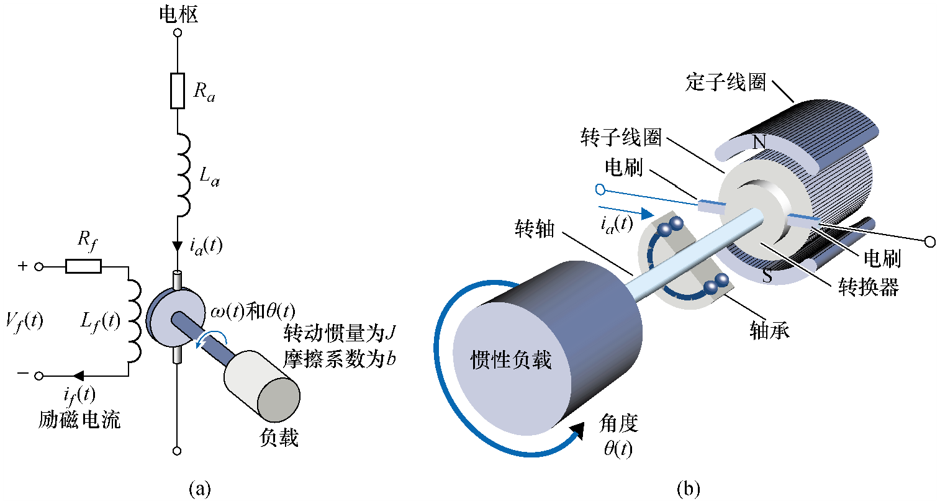

令 $\theta(t)$ 为电机输出的转角，$V_f (t) $ 是电机的输入电压。对许多直流电机而言，常采用以下简化模型，


$$\tau_1 \ddot{\theta}  + \dot{\theta} = \frac{1}{\lambda} V_f$$


其中，$\tau_1 = 0.1, \lambda = 5$ 为电机的参数（常量）。基于单位反馈控制的框架，完成以下内容：

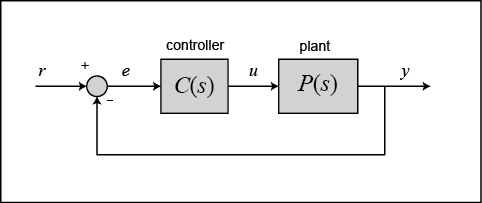

- 绘制电机系统的阶跃响应，给出其上升时间、稳定时间小于、 超调

- 设计控制器，使得闭环系统的阶跃响应满足以下要求：上升时间小于0.1s ；稳定时间小于0.8s ； 超调小于10%

- 绘制闭环系统的冲激响应，和在信号 $ \cos(t) + e^{-3t}$ 的响应轨迹

tau1 = 0.1;
lambda = 5;
P3 = tf(1/lambda,[tau1 1 0]);
T3_base = feedback(P3,1);
figure
step(T3_base)
grid on
title('单位反馈下电机系统阶跃响应')
info3_base = stepinfo(T3_base)
Kp3 = 120;
Kd3 = 12;
C3 = pid(Kp3,0,Kd3);
T3 = feedback(C3*P3,1);
figure
step(T3)
grid on
title('PD控制后的闭环阶跃响应')
info3 = stepinfo(T3)
figure
impulse(T3)
grid on
title('闭环冲激响应')
t3 = 0:0.001:5;
u3 = cos(t3)+exp(-3*t3);
y3 = lsim(T3,u3,t3);
figure
plot(t3,u3,'--','LineWidth',1.0)
hold on
plot(t3,y3,'LineWidth',1.2)
grid on
xlabel('t / s')
ylabel('幅值')
legend('输入','输出','Location','best')
title('对 cos(t)+e^{-3t} 的闭环响应')
%由 stepinfo 可知，PD 控制后的系统上升时间、调节时间以及超调量均满足设计指标

## 题目4

双质量块弹簧阻尼模型，在机器人领域常称为**双惯量系统，**广泛用于机械臂的控制。例如，谐波减速器驱动机械臂和柔性关节机械臂。下图是双质量块弹簧阻尼模型的原理图。

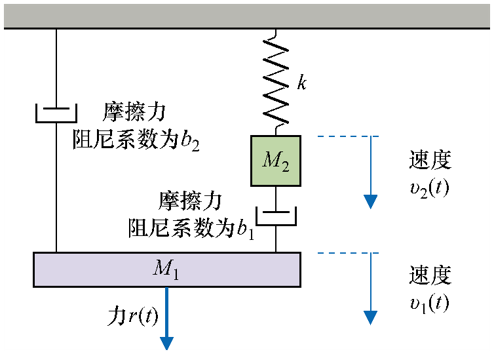

令质量块1的位置为 $x_1$, 质量块2的位置为 $x_2$。有


$$M_1  \ddot{x}_1 + (b_1 + b_2 ) \dot{x}_1 - b_2  \dot{x}_2 = r (t) \\ 
M_2 \ddot{x}_2 + b_1 ( \dot{x}_2 -  \dot{x}_1) + k x_2 = 0$$


考虑系统的输出为 $x_1(t)$ 。请完成以下内容

- 绘制该系统的开环响应，判断系统是否稳定

- 依然采用单位反馈控制的框架（见题目3），设计控制器，使得闭环系统的阶跃响应满足以下要求：上升时间小于0.5s ；稳定时间小于4s ； 超调小于10%

M1 = 1;
M2 = 1;
b1 = 1;
b2 = 1;
k4 = 1;
A4 = [0 1 0 0;0 -(b1+b2)/M1 0 b2/M1;0 0 0 1;0 b1/M2 -k4/M2 -b1/M2];
B4 = [0;1/M1;0;0];
C4p = [1 0 0 0];
D4 = 0;
P4 = ss(A4,B4,C4p,D4);
poles4_open = pole(P4)
open_loop_stable = isstable(P4)
figure
step(P4,0:0.01:10)
grid on
title('双惯量系统开环阶跃响应')
Kp4 = 15;
Kd4 = 5;
C4 = pid(Kp4,0,Kd4);
T4 = feedback(C4*P4,1);
figure
step(T4)
grid on
title('PD控制后的闭环阶跃响应')
info4 = stepinfo(T4)
closed_loop_stable = isstable(T4)
%事实上，由 poles4_open 可见系统存在零极点，同时 open_loop_stable = 0，
%因此开环系统不是渐近稳定系统，阶跃响应不存在有限稳态值。